# 1CWK50 submission

Full instructions on how to submit this live script are available in the assignment specification on Moodle ("How to submit your work" section). Make sure you read them carefully, and that you test your final submission thoroughly before uploading it to Moodle. No additional files can be accepted after the deadline has passed.

## 1. Dataset preparation (20%)

% check the dataset is present:
if ~exist('moons.csv', 'file')
    error('You need to download moons.csv from Moodle and place it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

%read dataset
data = readcell('moons.csv')

data = 151×3 cell array
    {'Feature 1'}    {'Feature 2'}    {'Label'  }
    {[   0.1567]}    {[   1.3182]}    {'Class A'}
    {[  -0.9705]}    {[   0.6211]}    {'Class A'}
    {[  -0.9086]}    {[   0.1598]}    {'Class A'}
    {[   0.7076]}    {[   0.2604]}    {'Class A'}
    {[  -1.2325]}    {[   0.9279]}    {'Class A'}
    {[  -0.6282]}    {[   0.8368]}    {'Class A'}
    {[   0.6124]}    {[   0.2656]}    {'Class A'}
    {[  -0.7009]}    {[  -0.0706]}    {'Class A'}
    {[   1.2655]}    {[   1.3637]}    {'Class A'}
    {[   0.4948]}    {[   0.9364]}    {'Class A'}
    {[  -0.5249]}    {[   1.0001]}    {'Class A'}
    {[  -0.8581]}    {[   0.2206]}    {'Class A'}
    {[  -1.3395]}    {[  -0.3469]}    {'Class A'}
    {[   0.9408]}    {[   0.1181]}    {'Class A'}
    {[  -1.4020]}    {[   0.4198]}    {'Class A'}



%show first 10 rows, look for target feature values
data(1:1:10, 1:1:end)

ans = 10×3 cell array
    {'Feature 1'}    {'Feature 2'}    {'Label'  }
    {[   0.1567]}    {[   1.3182]}    {'Class A'}
    {[  -0.9705]}    {[   0.6211]}    {'Class A'}
    {[  -0.9086]}    {[   0.1598]}    {'Class A'}
    {[   0.7076]}    {[   0.2604]}    {'Class A'}
    {[  -1.2325]}    {[   0.9279]}    {'Class A'}
    {[  -0.6282]}    {[   0.8368]}    {'Class A'}
    {[   0.6124]}    {[   0.2656]}    {'Class A'}
    {[  -0.7009]}    {[  -0.0706]}    {'Class A'}
    {[   1.2655]}    {[   1.3637]}    {'Class A'}



%read observations sans feature names
obs = data(2:end,:);

%shuffle observations
obs_shuffled = obs(randperm(size(obs,1)), :);



%use 40% for testing data
nTest = round(0.4 * size(obs_shuffled,1))

nTest = 60


%split horizontally

%copy out shuffled testing data (40%)
obs_test = obs_shuffled(1:1:nTest, :);
%copy out shuffled training data (remaining 60%)
obs_train = obs_shuffled(nTest+1:1:end, :);

%column index of target feature values, in this case 3
label_index = 3;

%vertical split 1
%seperate examples & labels for testing obs
test_labels = categorical(obs_test(:, label_index));
test_examples = cell2mat(obs_test(:, 1:end~=label_index));

%check sizes 
size(test_examples)

ans =     60     2


size(test_labels)

ans =     60     1



%vertical split 2

%%seperate examples & labels for training obs
train_labels = categorical(obs_train(:, label_index));
train_examples = cell2mat(obs_train(:, 1:end~=label_index));

%check sizes
size(train_examples)

ans =     90     2


size(train_labels)

ans =     90     1


## 2. Feature space visualisation (20%)

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:
m_nb = fitcnb(train_examples, train_labels)

m_nb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [Class A    Class B]
            ScoreTransform: 'none'
           NumObservations: 90
         DistributionNames: {'normal'  'normal'}
    DistributionParameters: {2×2 cell}


  Properties, Methods



test_nb = fitcnb(test_examples,test_labels)

test_nb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [Class A    Class B]
            ScoreTransform: 'none'
           NumObservations: 60
         DistributionNames: {'normal'  'normal'}
    DistributionParameters: {2×2 cell}


  Properties, Methods


predictions = m_nb.predict(test_examples);
p_nb = sum(predictions == test_labels) / length(test_labels)

p_nb = 0.8500

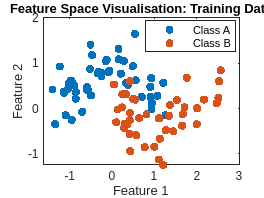

%draw figure for training labels
figure;

% gscatter graph for training data
gscatter(m_nb.X(:,1),m_nb.X(:,2),m_nb.Y)

%Graph labels and title
title("Feature Space Visualisation: Training Data");
xlabel("Feature 1");
ylabel("Feature 2");

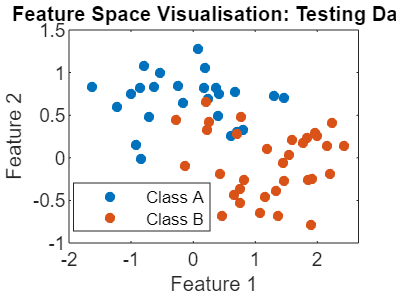


%new figure for testing labels
figure;


%gscatter graph for testing data
gscatter(test_nb.X(:,1),test_nb.X(:,2), test_nb.Y)

%Graph labels and title
title("Feature Space Visualisation: Testing Data");
xlabel("Feature 1");
ylabel("Feature 2");

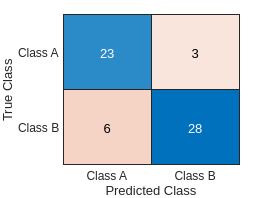


%confusionchart showing which true class v predicted class
%shows 9 incorrectly classified

confusionchart(test_labels, predictions)


%logical test for defining wrongly predicted
wronglyPredicted = predictions ~= test_labels

wronglyPredicted = 60×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


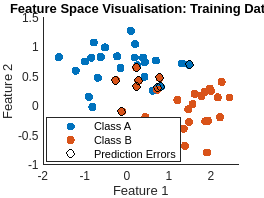



%new figure plot
figure;
%allow new figure plot to be drawn over
hold('on');

%redraw gscatter
gscatter(test_nb.X(:,1),test_nb.X(:,2), test_nb.Y)
%draw over gscatter with a scatter that highlights the 9 wrongly predicted
%labels
scatter(test_examples(wronglyPredicted,1), test_examples(wronglyPredicted,2), 'ok', 'DisplayName', 'Prediction Errors');

%Graph labels and title
title("Feature Space Visualisation: Training Data");
xlabel("Feature 1");
ylabel("Feature 2");

## 3. Abstraction visualisations (20%)

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

%fit training values to knn classifier using 1 nearest neighbour value
m_knn1 = fitcknn(train_examples, train_labels, 'NumNeighbors', 1)

m_knn1 =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Class A    Class B]
           ScoreTransform: 'none'
          NumObservations: 90
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


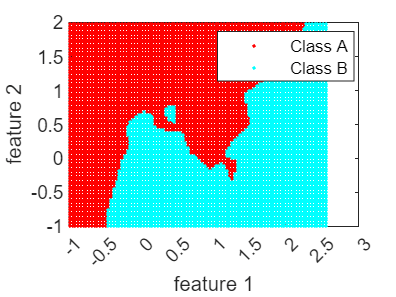


%use visualise_abstraction function with m_knn1 parameter to create
% scatter graph
visualise_abstraction(m_knn1)
%label axes
xlabel("feature 1")
ylabel("feature 2")



%fit training values to knn classifier using 5 nearest neighbour value
m_knn5 = fitcknn(train_examples, train_labels, 'NumNeighbors', 5)

m_knn5 =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Class A    Class B]
           ScoreTransform: 'none'
          NumObservations: 90
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


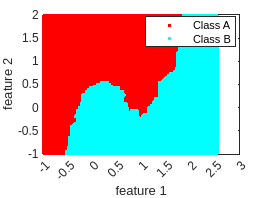


%use visualise_abstraction function with m_knn5 parameter to create
% scatter graph
visualise_abstraction(m_knn5)


%label axes
xlabel("feature 1")
ylabel("feature 2")




%%%%%%%%%%%%decision tree%%%%%%%%%%%%%%%%%%%%%%%

%fit training values to decision tree classifier using minimum parent size
%of 10, no merging and no pruning

m_dt10 = fitctree(train_examples,train_labels,"MinParentSize",10,"Prune","off","MergeLeaves","off")

m_dt10 =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Class A    Class B]
           ScoreTransform: 'none'
          NumObservations: 90


  Properties, Methods


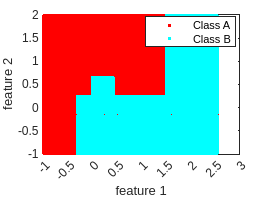



%use visualise_abstraction function with m_dt10 parameter to create
% scatter graph
visualise_abstraction(m_dt10)

%label axes
xlabel("feature 1")
ylabel("feature 2")


%fit training values to decision tree classifier using minimum parent size
%of 1, no merging and no pruning
m_dt1 = fitctree(train_examples,train_labels,"MinParentSize",1,"Prune","off","MergeLeaves","off")

m_dt1 =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Class A    Class B]
           ScoreTransform: 'none'
          NumObservations: 90


  Properties, Methods


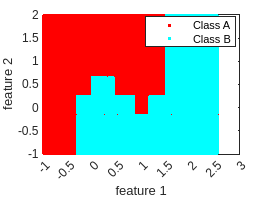


%use visualise_abstraction function with m_dt1 parameter to create
% scatter graph
visualise_abstraction(m_dt1)


%label axes
xlabel("feature 1")
ylabel("feature 2")

## 4. Classifier re-implementations (20%)

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

%%%%%%%%%%%%%% K-Nearest-Neighbors %%%%%%%%%%%%%%%%%

%fit training values to own knn classifier using 1 nearest neighbour value
zknn1 = my_fitcknn(train_examples, train_labels, 'NumNeighbors', 1)

zknn1 =   my_ClassificationKNN with properties:

               X: [90×2 double]
               Y: [90×1 categorical]
    NumNeighbors: 1
         Verbose: 0


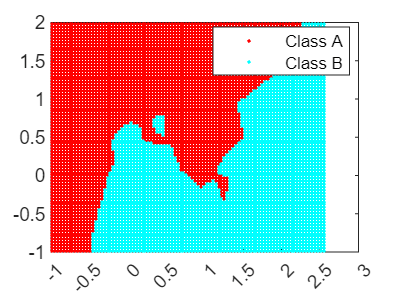


%use visualise_abstraction function with zknn1 parameter to create
% scatter graph
visualise_abstraction(zknn1)


%fit training values to own knn classifier using 5 nearest neighbour value
zknn5 = my_fitcknn(train_examples, train_labels, 'NumNeighbors',5)

zknn5 =   my_ClassificationKNN with properties:

               X: [90×2 double]
               Y: [90×1 categorical]
    NumNeighbors: 5
         Verbose: 0


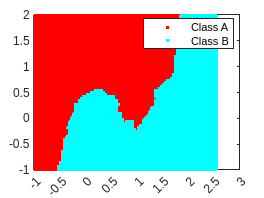


%use visualise_abstraction function with zknn5 parameter to create
% scatter graph
visualise_abstraction(zknn5)





%%%%%%%%%%%%%% Decision Tree %%%%%%%%%%%%%%%%%

zdt10 = my_fitctree(train_examples,train_labels,"MinParentSize",10)

zdt10 =   my_ClassificationTree with properties:

                X: [90×2 double]
                Y: [90×1 categorical]
    MinParentSize: 10
     MaxNumSplits: 89
          Verbose: 0
             Root: [1×1 struct]


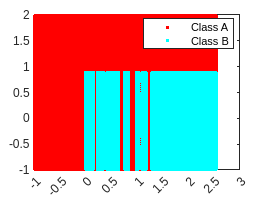


visualise_abstraction(zdt10)


zdt1 = my_fitctree(train_examples,train_labels,"MinParentSize",1)

zdt1 =   my_ClassificationTree with properties:

                X: [90×2 double]
                Y: [90×1 categorical]
    MinParentSize: 1
     MaxNumSplits: 89
          Verbose: 0
             Root: [1×1 struct]



visualise_abstraction(zdt1)

## 5. Extension to ensembles (20%)

% i couldnt get this to work, did attempt the soft voting function but ran
% out of time to fix it

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:
ensembleNB = predict(m_nb,m_nb.X)

ensembleNB = 90×1 categorical array
     Class A 
     Class B 
     Class B 
     Class A 
     Class A 
     Class B 
     Class A 
     Class A 
     Class B 
     Class B 
     Class B 
     Class B 
     Class A 
     Class A 
     Class B 
     Class A 
     Class B 
     Class B 
     Class B 
     Class A 
     Class A 
     Class B 
     Class B 
     Class B 
     Class B 
     Class B 
     Class B 
     Class A 
     Class B 
     Class B 


ensembleNB_num = double(ensembleNB)

ensembleNB_num =      1
     2
     2
     1
     1
     2
     1
     1
     2
     2


ensembleKNN = predict(zknn5,zknn5.X)

ensembleKNN = 1×90 categorical array
     Class A      Class B      Class B      Class A      Class B      Class B      Class A      Class A      Class B      Class B      Class B      Class A      Class A      Class A      Class A      Class B      Class B      Class B      Class B      Class A      Class A      Class B      Class B      Class B      Class B      Class B      Class B      Class A      Class B      Class B      Class B      Class A      Class A      Class B      Class A      Class A      Class A      Class A      Class A      Class B      Class A      Class A      Class A      Class A      Class A      Class B      Class A      Class B      Class A      Class B      Class A      Class A      Class B      Class B      Class A      Class B      Class A      Class B      Class A      Class A      Class A      Class B      Class A      Class B      Class B      Class A      Class A      Class B      Class B      Class B      Class A      Class A      Class A      Class B  



ensembleKNN_num = double(ensembleKNN)

ensembleKNN_num =      1     2     2     1     2     2     1     1     2     2     2     1     1     1     1     2     2     2     2     1     1     2     2     2     2     2     2     1     2     2     2     1     1     2     1     1     1     1     1     2     1     1     1     1     1     2     1     2     1     2


weights = [0.5, 0.5]

weights =     0.5000    0.5000





final_pred1 = soft_voting(ensembleNB_num, ensembleKNN_num, weights)

final_pred1 =      1
     2
     2
     1
     2
     2
     1
     1
     2
     2


visualise_abstraction(final_pred1)

Dot indexing is not supported for variables of this type.

Error in visualise_abstraction (line 25)
  hundredth = round((max(m.X(:,1)) - min(m.X(:,2))) / 100,3);